# Plotting the Path of Hurricane Ike

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

ike = readtable("./data/ike.csv");
ikeLat = ike.ikeLat;
ikeLon = ike.ikeLon;
ikeWS = ike.ikeWS;

## Tasks 1 & 2

Latitude and longitude data for Hurricane Ike, along with the wind speed along the path, have been loaded into the workspace.  

There are special functions to plot geographic data.  The `geoplot` function creates a line plot of latitudes and longitudes.  So it is handy to show a trajectory.  

`gp` `=` `geoplot``(``lat``,``lon``)`

Like many plotting functions, you aren't required to assign the output to a variable unless you want to use the handle for customization later, which we do.

You may have noticed that `g` is a line plot, just like the output of the `plot` function.  There are some differences, like `g` has `LatitudeData` and `LongitudeData` properties where `plot` output had `XData` and `YData` properties.

You can customize the geoplot using either dot notation or name-value pairs and line specs.

g = geoplot(ikeLat, ikeLon)

g =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
       LatitudeData: [17.2000 17.8000 19.8000 21.8000 23.6000 22.8000 21.2000 21.1000 21.5000 23.1000 24.7000 26.1000 28.3000 33.5000 43.3000]
      LongitudeData: [323 318.7000 312.7000 306.5000 301 295.1000 289.7000 284.8000 279.7000 276 273.6000 270 266 265.1000 278.5000]

  Show all properties


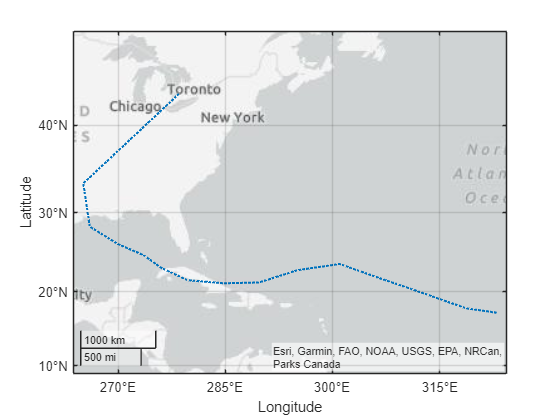

g.LineStyle = ":";
g.LineWidth = 1.5;

## Tasks 3 & 4

At each latitude and longitude in the data, the wind speed was measured.  Scatter plots allow you to use the size and color of individual markers as an extra dimension of information.  The `geoscatter` function is the map-based version of a `scatter` plot.

`geoSc` `=` `geoscatter``(``ikeLat``,``ikeLon``)`

You can pass `"filled"` as an additional input to the `geoscatter` and `scatter` functions to fill in the markers.

You may notice that again, the graphics object is a familiar type: a `scatter` object.  You can do similar customizations as you could with a plot created with the `scatter` function.

The `SizeData` property controls the size of the markers.  To make them all the same size, set that property to a constant.  You can make them different sizes by setting that property equal to a vector that is the same length as your data.

`geoSc.SizeData` `=` `10`

`geoSc.SizeData` `=` `vec`

hold on
gs = geoscatter(ikeLat, ikeLon, "filled")

gs =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
       LatitudeData: [17.2000 17.8000 19.8000 21.8000 23.6000 22.8000 21.2000 21.1000 21.5000 23.1000 24.7000 26.1000 28.3000 33.5000 43.3000]
      LongitudeData: [323 318.7000 312.7000 306.5000 301 295.1000 289.7000 284.8000 279.7000 276 273.6000 270 266 265.1000 278.5000]
              ZData: [1×0 double]
           SizeData: 36
              CData: [0.8500 0.3250 0.0980]

  Show all properties


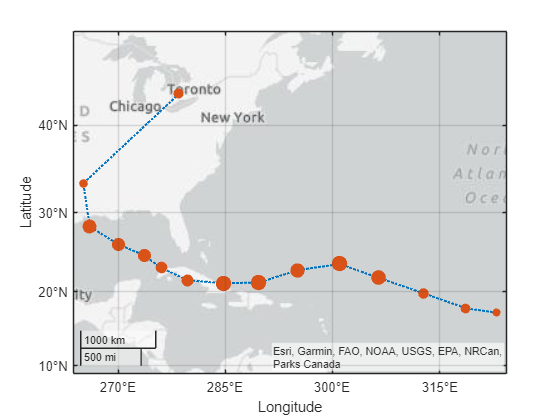

hold off
gs.SizeData = ikeWS;

## Task 5

The color of a line plot is defined in the `Color` property, which is an 1-by-3 RGB vector.  The color of the markers in a scatter plot is stored in the `CData` property.

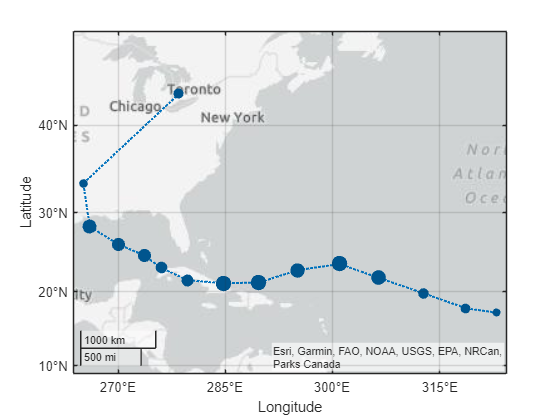

col = g.Color;
gs.CData = col*.75;

## Task 6

As you have seen, the properties of the `geoplot` and `geoscatter` objects are very similar to the properties of the  graphics objects created by `plot` and `scatter`.  However, these graphs are drawn on top of a different type of axes called `GeographicAxes`.

ax = gca

ax =   GeographicAxes with properties:

     Basemap: 'streets-light'
    Position: [0.1300 0.1100 0.7750 0.8150]
       Units: 'normalized'

  Show all properties


## Task 7

Different axes have different properties. Geographic axes have a property that controls the look of the underlying map.

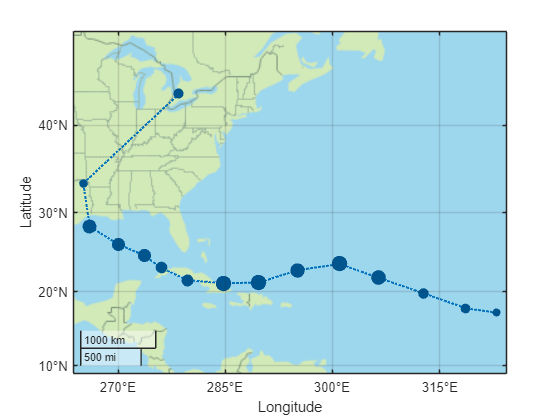

ax.Basemap = "bluegreen";